# pwelch concept

Welch’s power spectral density estimate

## the concept and implementation of Welch's method

### full FFT method

full FFT is basically just doing one Fourier transform over the entire duration of the signal.

this method is totally fine,and  there's nothing wrong with this procedure. but you can see there are a lot of non stationarity x' and temporal dynamics in this time domain signal.

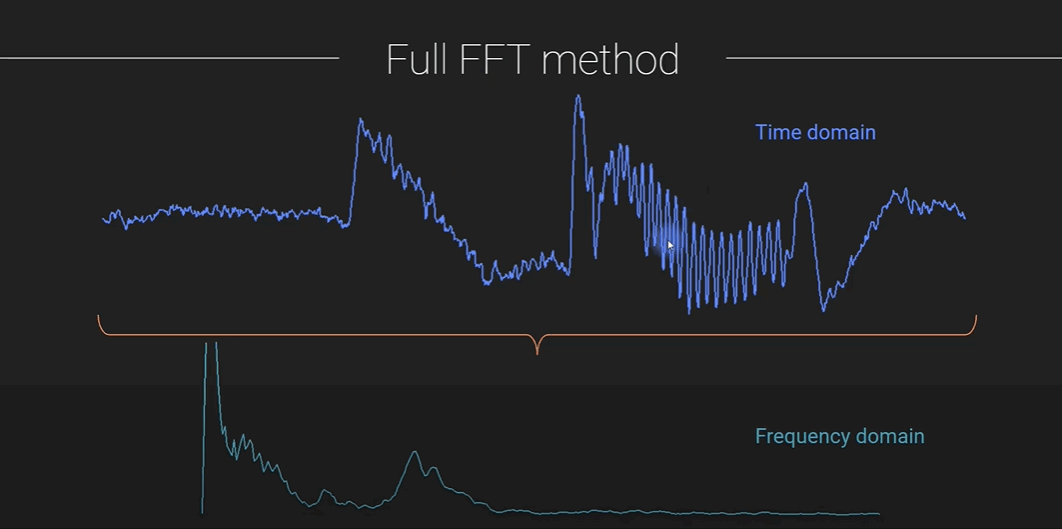

### Welch's method

the idea of Welch's method is that instead of doing the Fourier transform on the entire time window, you just isolate a little piece of the data, so let's say you take this much data, maybe 200 milliseconds, this is one of the parameters of the Welch's method you ahve to decide how wide to make this time window here. so you take these data, kind of cut out this snippet , you isolate this snippet ignore the rest of this time series . you also have to taper these data, pinching the ends of the signals so that the begining and the end are going to zero, and then with this little snippet, we take the Fourier transform and we compute the power spectrum and that looks like this , so this is like the power spectrum,  not of the entire signal but just of this little snippet ,then we take another little sinppet of the signal, so you can see ,in this case , the window is the same size, here is another parameter of Welch's method which is wether and how much to overlap these two windows, so what you see is now i'm overlapping by 50%, so 50% of the second window starts at 50% of the way through the forst time window, then we take out this little snippet of data here again, apply a tapeer which means sort of pinching off the star in the end points and then take the Fourier transform of this snippet, so now we see that the power spectrum here looks a little bit different from how it looks here , and so on snd so on and son on then i'm just drawing another snippet over here and then it's power spectrum looks something like this and then we average all of these power spectra together, so notice we are still ending up with the spectral chatacteristics of the entire signal, however we are putting that spectrum together oen piece at a time.

here you see a comparision of Welch's method and the full of FFT,, we can see that they are overall quite similar , Welch's method is much smoother, it gives a much smoother spectrum and that is generally the result of Welch's  method,it's gping to smooth out the power spectrum quite a bit.

#### tapering each data snippet

taper the signal and end up with this orange signal, so youcan see that it's pinching off towards zero at the begining at the end and it is full amplitude in the middle, now the reason for the taper is that you have edges here and edges here. so these edges are going to cause artifacts in the Fourier transform, these are edge effects, essentially these are strong  non-stationarity x' that take a lot of energy and a lot of frequecies for the Fourier transform to represent, so we taper the data to minimaize the amount of edge effects contaminating the power spectrum. now you can also see that we re getting rid of a lot of valid data, so there's nothing wrong with the data here in the blue signal and yet we are tapering this down so we are attenuating valid signal , that is one of motivations for having these windows overlap, so this part of the signal here is attenuated by the taper in this window , but in this window we actually get this tapered piece to be at full amplitude, so that's why having some overlap  is a good idea, 

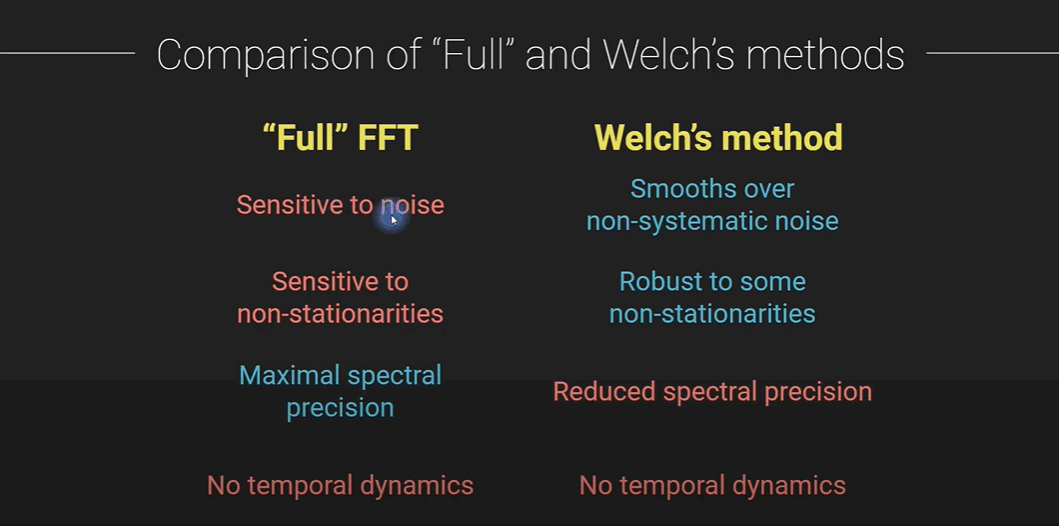

## analysis parameters

## comparision of " full FFT" and Welch's method

the idea behind Welch's method  for estimating the power spectrum is to take the avaliable data split it up into segments, compute periodic ram from segment and then average the results and  the motivation for doing this is to reduce the variance that is associated with the periodic ram estimate of the power spectrum.

recall that the variance of the periodic ram is proportional to the square of the value of the spectrum itself, so as the number of data point increases, the variance doesn't decrease. and in this approach we can take advantage of averaging independent estimates to reduce the variance. 

so the example 

**Welch Estimate Using Default Inputs**

Obtain the Welch PSD estimate of an input signal consisting of a discrete-time sinusoid with an angular frequency of *π*/4 rad/sample with additive *N*(0,1) white noise.

Create a sine wave with an angular frequency of *π*/4 rad/sample with additive *N*(0,1) white noise. Reset the random number generator for reproducible results. The signal has a length *N**x*=320 samples.

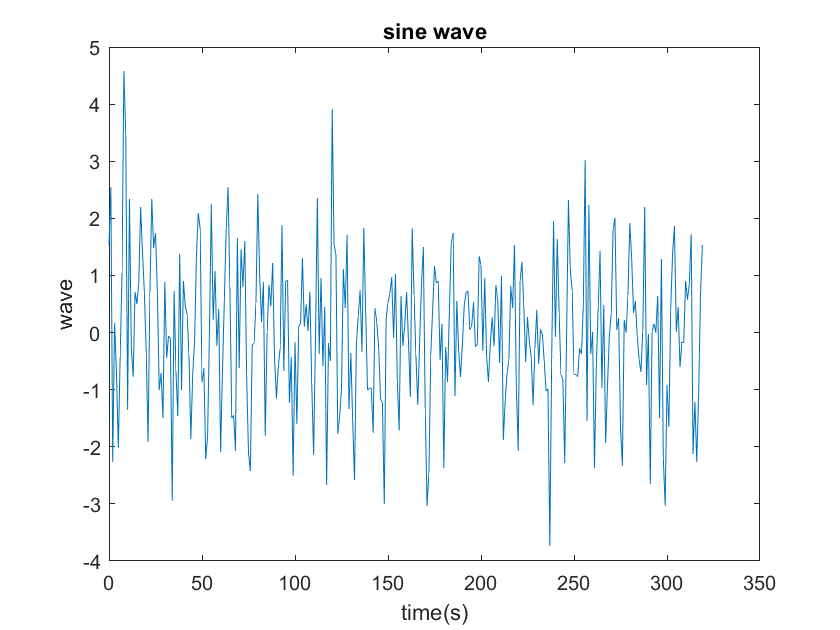

rng default

n = 0:319;
x = cos(pi/4*n)+randn(size(n));

figure
plot(n,x)
xlabel('time(s)')
ylabel('wave')
title('sine wave')